a = 0.001/7;
r= 0.15;
ro = 0.03;
f = @(t,y) [-a*y(1)*y(2)+ro*y(3); a*y(1)*y(2) - r*y(2); r*y(2)-ro*y(3)];
y0 = [10000;1;0];
t0 = 0;
tf = 50;
h = 1;
reltol = 10e-9;
[t,y] = rkf45(f,y0,t0,tf,h,reltol,1000);

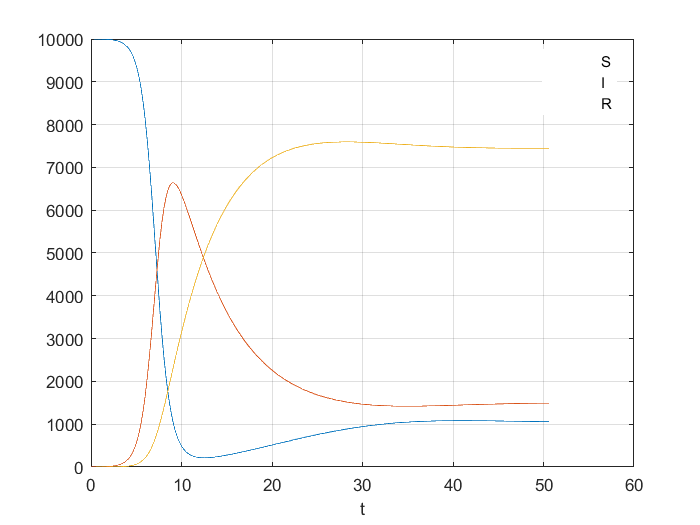

plot(t,y);
xlabel('t');
legend('S','I','R','location','best');
grid on;

length(t0:h:tf)

ans = 51